%Open-sourced implementation of 'element-space' UCA MUSIC.
close all; clear all; tic;

% === Parameters ===
N = 5; %No. of antenna elements
r = 0.5; %Array radius
T = 200; %No. of snapshots
D = 2; %No. of sources

theta0 = [90, 90]; phi0 = [210, 245]; %True source DoAs
SNR_dB = 20; 
f = 5e8; %Carrier freq
theta = deg2rad(theta0); phi = deg2rad(phi0);
lambda = 3e8/f;
gamma_n = 2*pi*(0:N-1)/N; %Angular position of antenna ele
ko = 2*pi/lambda;


% === Steering Matrix ===
A = zeros(N, D);
for i = 1:D
    A(:,i) = exp(1j * ko * r * sin(theta(i)) * cos(phi(i) - gamma_n'));
end

% === Coherent Signal Generation (multipath model) ===
delay = 5; r1 = sqrt(0.6); r2 = sqrt(0.4);
%delay = 5; r1 = sqrt(0.4); r2 = sqrt(0.6); %Uncomment to see what happens
%in a non-minimum-phase channel scenario! (i.e stronger reflection compared
%to LOS)
fs = 1e6;              % Example: 1 MHz sampling rate
Ts = 1/fs;             % Sampling period
t = (0:T-1)*Ts;        % Time in seconds

s1 = exp(1j*2*pi*f*t);
s2 = [zeros(1, delay), s1(1:end-delay)];
S_coh = [s1; s2];
X_signal = A * diag([r1, r2]) * S_coh;
SNR_lin = 10^(SNR_dB / 10);
noise_power = mean(abs(X_signal(:)).^2) / SNR_lin;
n = sqrt(noise_power/2)*(randn(N,T)+1j*randn(N,T));
X = X_signal + n;


% === Covariance and Noise Subspace ===
R = (1/T) * (X * X');
[vec, lambda] = eig(R);
[~, idx] = sort(diag(lambda), 'descend');
vec = vec(:, idx); vn = vec(:, D+1:end);


% === MUSIC Spectrum ===
theta_scan = 0:1:90; phi_scan = 0:1:360; %Finer the resolution, more will be computation time.
P = zeros(length(theta_scan), length(phi_scan));
for i = 1:length(theta_scan)
    th = deg2rad(theta_scan(i));
    for j = 1:length(phi_scan)
        ph = deg2rad(phi_scan(j));
        a = exp(1j*ko*r*sin(th)*cos(ph - gamma_n'))';
        P(i,j) = 1 / (a * (vn * vn') * a');
    end
end
P_dB = 10*log10(abs(P) / max(abs(P(:))));

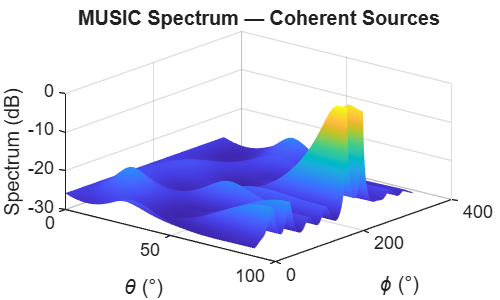


% === Plot ===
figure;
surf(theta_scan, phi_scan, P_dB'); shading interp;
xlabel('\theta (°)'); ylabel('\phi (°)'); zlabel('Spectrum (dB)');
title('MUSIC Spectrum — Coherent Sources'); view(40, 35);


% === DOA Estimation ===
fprintf('\n--- Estimated DOAs (Coherent Sources) ---\n');


--- Estimated DOAs (Coherent Sources) ---


P_norm = abs(P) / max(abs(P(:)));
peaks = imregionalmax(P_norm);
vals = P_dB(peaks); idxs = find(peaks);
[~, top_idx] = maxk(vals, min(D, length(vals)));
for k = 1:length(top_idx)
    [ti, pi] = ind2sub(size(P), idxs(top_idx(k)));
    fprintf('Peak #%d → θ = %.2f°, φ = %.2f°, Power = %.2f dB\n', ...
        k, theta_scan(ti), phi_scan(pi), P_dB(ti, pi));
end

Peak #1 → θ = 87.00°, φ = 210.00°, Power = 0.00 dB
Peak #2 → θ = 84.00°, φ = 245.00°, Power = -1.42 dB



toc;

Elapsed time is 1.435821 seconds.
